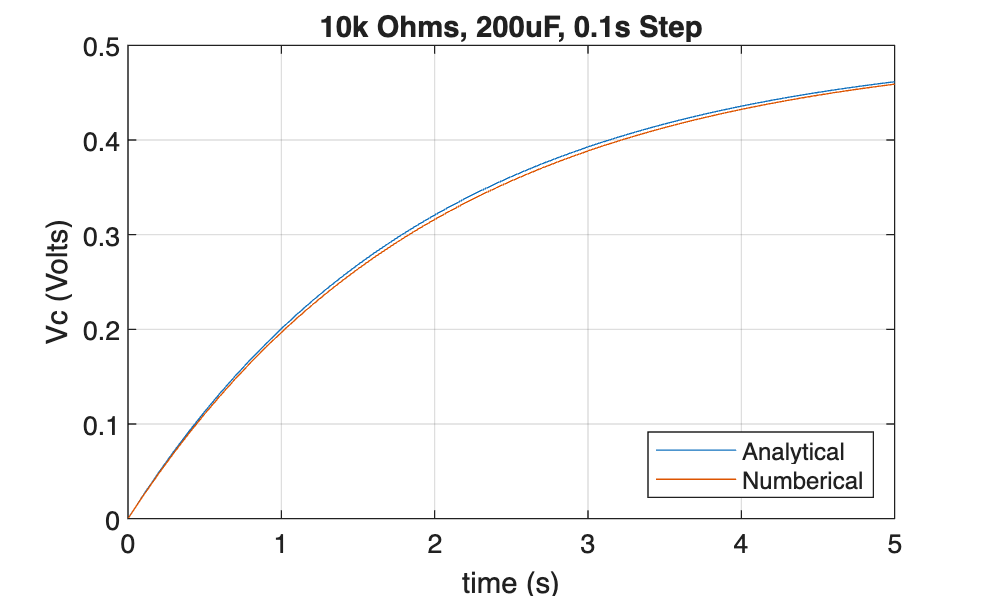

clc; clear;

% General Solution
Vs = 0.5;
Vc_t = @(tau, t) Vs * (1 - exp(-t ./ tau));


% Import .csv data
A1 = readtable("RC_Circut_output_a1.csv");
A2 = readtable("RC_Circut_output_a2.csv");
B1 = readtable("RC_Circut_output_b1.csv");
B2 = readtable("RC_Circut_output_b2.csv");

% Plot
grid on;
plot(A1.t, A1.Vc, A1.t, Vc_t(2, A1.t))
title("10k Ohms, 200uF, 0.1s Step");
xlabel("time (s)");
ylabel("Vc (Volts)");
legend ('Analytical', 'Numberical','Location','southeast');
grid on;

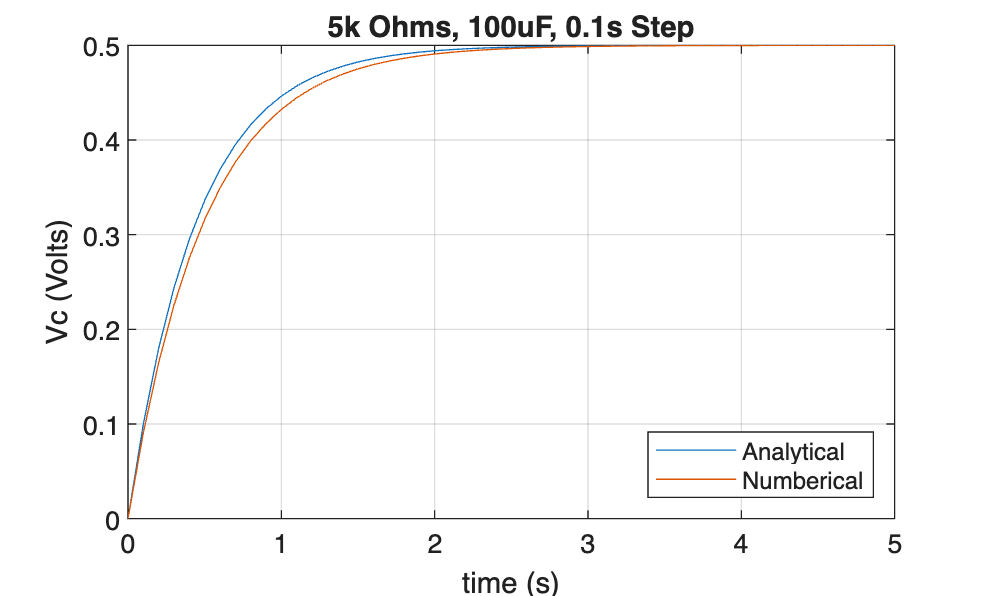



plot(A2.t, A2.Vc, A2.t, Vc_t(0.5, A2.t))
title("5k Ohms, 100uF, 0.1s Step");
xlabel("time (s)");
ylabel("Vc (Volts)");
legend ('Analytical', 'Numberical','Location','southeast');
grid on;

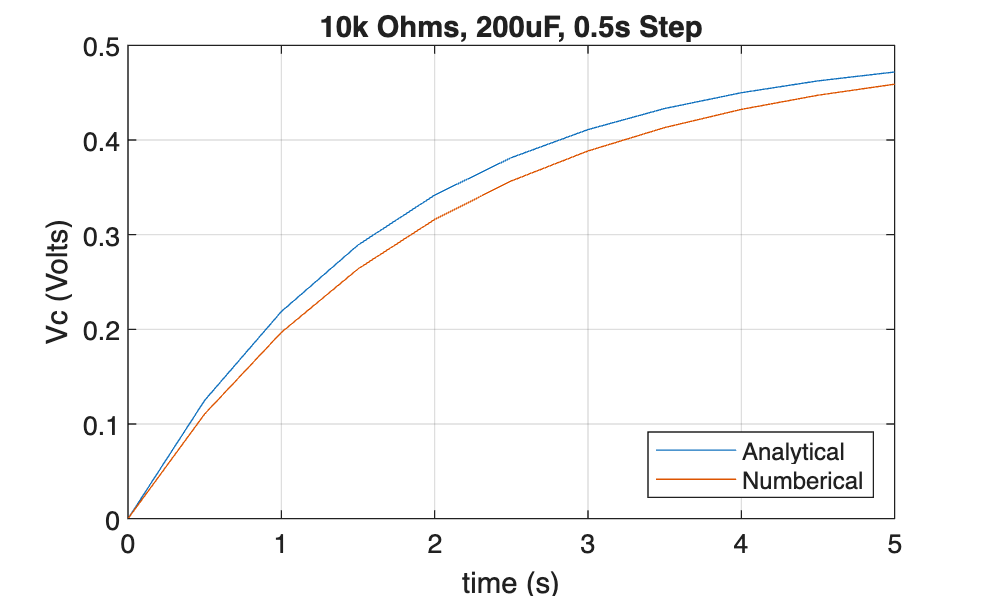



plot(B1.t, B1.Vc, B1.t, Vc_t(2, B1.t))
title("10k Ohms, 200uF, 0.5s Step");
xlabel("time (s)");
ylabel("Vc (Volts)")
legend ('Analytical', 'Numberical','Location','southeast');
grid on;

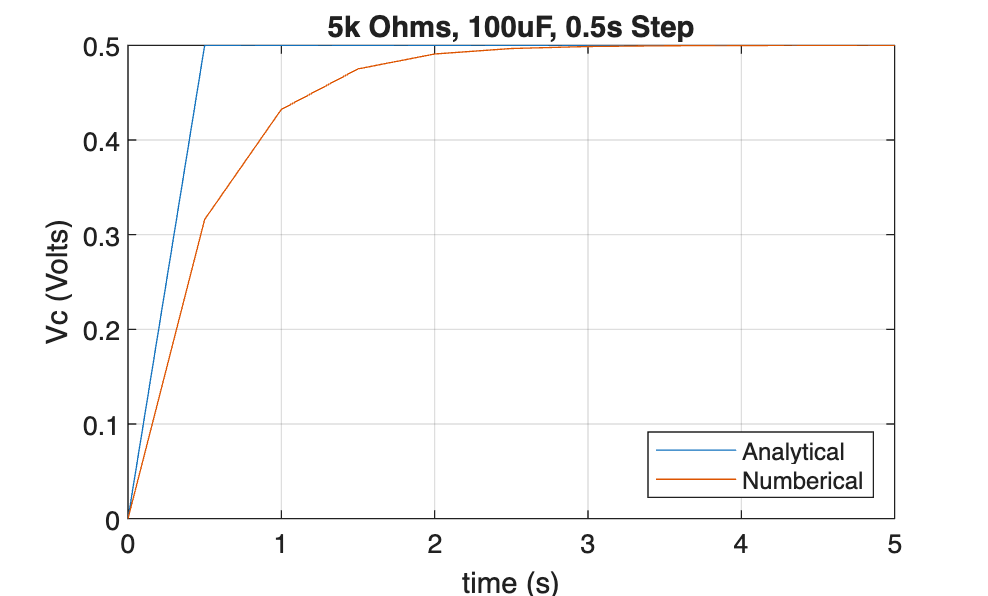



plot(B2.t, B2.Vc, B2.t, Vc_t(0.5, B2.t))
title("5k Ohms, 100uF, 0.5s Step");
xlabel("time (s)");
ylabel("Vc (Volts)");
legend ('Analytical', 'Numberical','Location','southeast');
grid on;